## T ASK 1

Definiamo, innanzitutto, le variabili `p` e `q``. `La variabile `p` è relativa al nome 'Nome`' e `la variabile `q` al cognome 'Cognome'. Per effettuare le operazioni seguenti, abbiamo bisogno della definizione della funzione data in consegna, ossia    $e^{-0.6x} \cdot \left(cos \left(\frac {p \cdot x}{2}\right)\right)^2 +  \frac {q}{1+3x^2}sin(\pi x)-2$$$ 

Per fare ciò, viene definita una** funzione anonima**, detta `funrif`, con la seguente sintassi: '`nomefunzione = @(x) funzione`'. Considerando che l'argomento `x` della funzione `funrif` è un vettore, si fa attenzione a inserire oppurtunamente gli operatori matematici ricordando che le operazioni sono componente per componente. 

p = length('Nome')

p =      4


q = length('Cognome')

q =      7


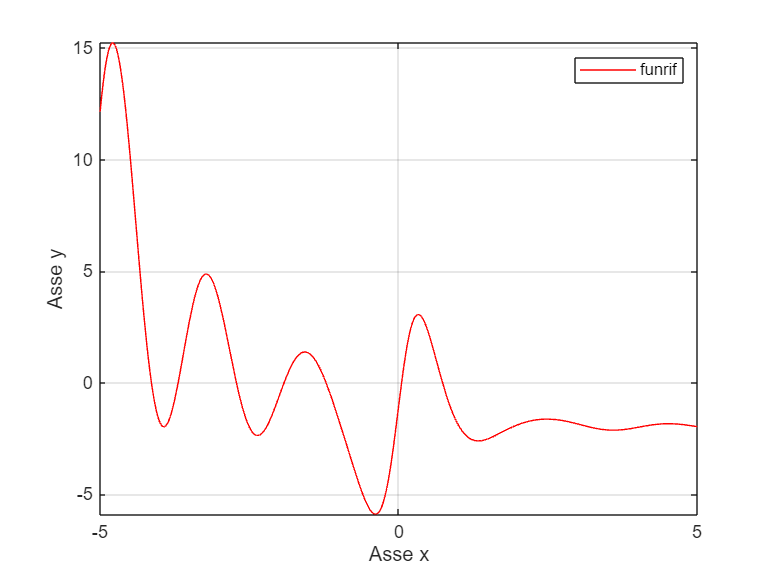

figure(1)
funrif = @(x) exp(-0.6*x).*(cos(p.*x/2)).^2+q./(1+3.*x.^2).*sin(pi*x)-2; %%rappresento la funzione
fplot(funrif, 'r')
legend('funrif')
xlabel('Asse x')
ylabel('Asse y')
grid on

## TASK 2

A questo punto, rappresentiamo `funrif `con i seguenti comandi:

- `figure('Name', Value)` crea la figura sottostante;

- `fplot(function, xinterval, LineSpec, options) `che ha come argomenti: `funrif`, $\left\lbrack -4,1\right\rbrack$ (l'intervallo iniziale) e il colore da assegnare al grafico della funzione, ossia il rosso (`'r'`);

- `grid on`, è utilizzato per visualizzare la griglia nella rappresentazione sottostante;

- `hold on` offre la possibilità di sovrappore nuovi grafici a quelli già esistenti (in questo caso abbiamo la funzione in rosso e la linea, relativa all'intervallo, in nero). 

- `title(target, titletext, options)` è necessario per inserire il titolo nella visualizzazione che, in questo caso, è `funrif `scritta in formato` 'latex' (`ciò è possibile grazie all'opzione '`Interpreter`', offerta dallo stesso comando`);`

- `legend(label, options) `è indispensabile per rendere leggibile il grafico, specificando a quale elemento è associato ogni singolo simbolo;

- `hold off `serve per disattivare la funzione` hold.`

Si sceglie poi un **sottointervallo** $\left\lbrack a,b\right\rbrack \;$ove ci sono: due punti di minimo, due punti di massimo e cinque zeri`. `

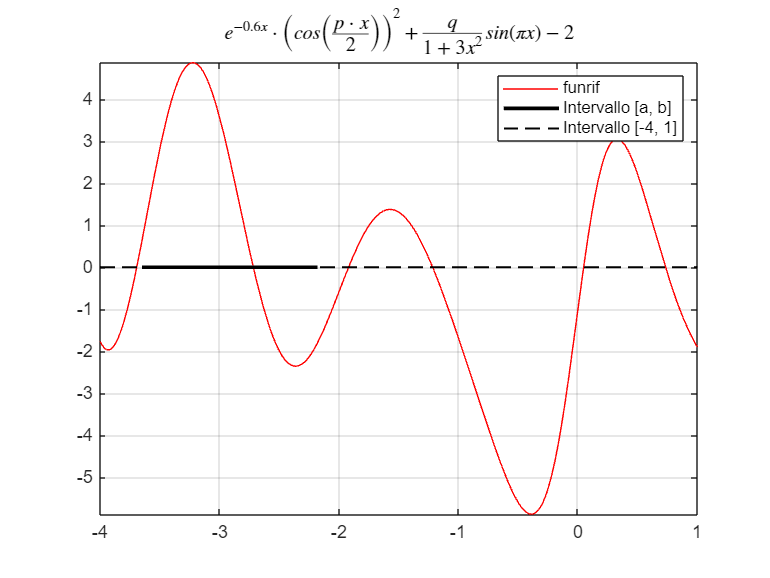

a = -3.65;
b = -2.18;
figure(2)
fplot(funrif, [-4, 1], 'r')
grid on
hold on
plot([a b], [0 0], 'k', 'LineWidth', 2)
plot([-4 1], [0 0], '--k', 'LineWidth', 1)
title('$e^{-0.6x} \cdot \left(cos \left(\frac {p \cdot x}{2}\right)\right)^2 +  \frac {q}{1+3x^2}sin(\pi x)-2$', 'Interpreter','latex')
legend('funrif', 'Intervallo [a, b]', 'Intervallo [-4, 1]', 'Location', 'northeast')
hold off

## TASK 3

### Zero di una funzione

Sia $f$ una funzione di una variabile $f:\Re \to \Re$. Risolvere $f\left(x\right)=0$ significa trovare un numero $r$  tale che $r:f\left(r\right)=0$. $r\;$è detto:

- **soluzione **dell'equazione;

- **radice** dell'equazione;

- **zero** dell'equazione.

Dal punto di vista grafico, $r$ è l'**ascissa **del **punto di intersezione **del grafico della funzione $f\left(x\right)$ con l'**asse x**. La funzione può avere zeri multipli (si annulla anche qualche derivata). Un problema può essere **mal **o **ben condizionato**. 

I parametri che la funzione `fzero `ha a disposizione sono:

- `funrif` ossia la funzione di riferimento;

- `appriniz(i)`: un vettore che contiene le approssimazioni iniziali degli zeri della funzione.

La funzione è racchiusa in un `for` perchè i punti di interesse della consegna devono essere cinque nell'intervallo considerato ossia $\left\lbrack -3\ldotp 65,-2\ldotp 18\right\rbrack$. Le soluzioni che sono mostrate qui in questo codice sono considerate come esatte per i calcoli seguenti.

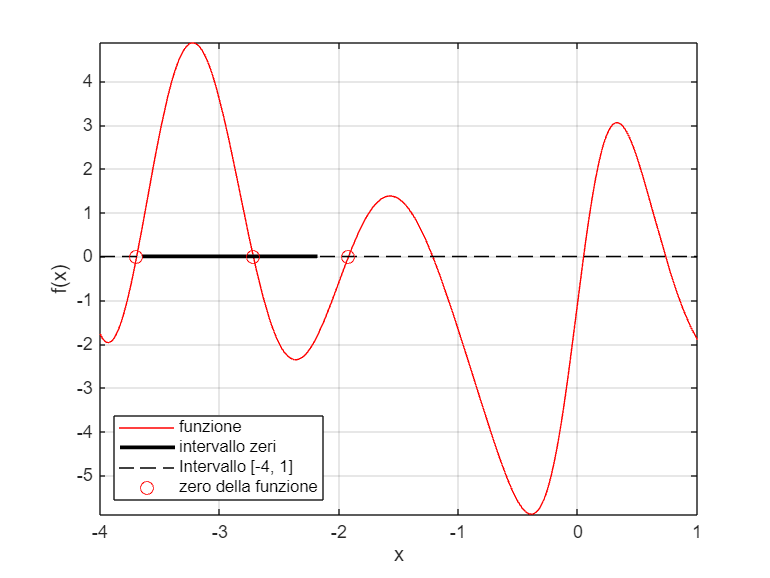

figure(3)
fplot(funrif, [-4, 1], 'r')
grid on
hold on
plot([a b], [0 0], 'k', 'linewidth', 2)
plot([-4, 1], [0, 0], '--k') %%linea tratteggiata nera
appriniz  = [-3.65, -3.40 , -2.91, -2.52, -2.18];
zfzero = zeros(1,5);
for i = 1:5
    zfzero(i) = fzero(funrif, appriniz(i)); %%zfzero è il vettore dei cinque zeri della funzione 
end
plot(zfzero, zeros(size(zfzero)), 'or', 'MarkerSize', 7) %%rappresenta tutti gli zeri dell'intervallo 
xlabel('x');
ylabel('f(x)');
legend('funzione', 'intervallo zeri', 'Intervallo [-4, 1]', 'zero della funzione', 'Location', 'southwest')
hold off

## TASK 4

### Minimi e massimi

Con $f\left(x\right)$ derivabile, il suo punto di minimo è dove si annulla la derivata di $f$ ossia $f^{\prime } \left(x\right)$.

Vengono calcolati i due **minimi** e i due **massimi **con la medesima funzione, offerta da Matlab, chiamata `fminbnd(funrif, estremo_sin, estremo_des)`. È una funzione utilizzata per trovare il minimo di una funzione univariata all'interno di un intervallo specificato negli argomenti della funzione. Ha un'**accuratezza**, ossia una precisione con cui i punti vengono approssimati all'interno dell'intervallo, di default pari a ${10}^{-6}$. In aggiunta, viene adoperato, per ogni valore calcolato per i minimi e i massimi, il comando `format long` che serve per impostare il formato di visualizzazione dei numeri a virgola mobile a lunga precisione. Viene calcolata, quindi, l'ascissa del primo minimo detta* punto di minimo 1*.

format long
minx_1 = fminbnd(@(x) funrif(x), -3.65, -3.40) %%ascissa del primo minimo

minx_1 =   -3.649963379326010


Qui di seguito, è mostrato il calcolo della sua ordinata, ossia il *valore minimo della funzione*.

format long
miny_1 = funrif(minx_1) %%ordinata del primo minimo

miny_1 =    0.625674628265426


Si hanno gli stessi calcoli per il *punto di minimo 2* e il *valore del minimo 2*:

format long
minx_2 = fminbnd(@(x) funrif(x), -2.80, -2.60) %%ascissa del secondo minimo

minx_2 =   -2.600056006716415


format long
miny_2 = funrif(minx_2)  %%ordinata del secondo minimo

miny_2 =   -1.267741656909884


Per utilizzare la funzione `fminbnd` per il calcolo dei *punti di massimo 1 e 2*, bisogna cambiare il segno della funzione($-f\left(x\right)$) nel modo riportato nelle righe seguenti. Questo perchè la funzione usata è adoperata per i minimi, quindi per calcolare i massimi, bisogna avere la funzione con segno opposto. Successivamente, si calcolano le ordinate dette *massimi di una funzione*.

format long
maxx_1 = fminbnd(@(x) -funrif(x), -3.19, -3.11) %%ascissa del primo massimo

maxx_1 =   -3.189941349005132


format long
maxy_1 = funrif(maxx_1) %%ordinata del primo massimo

maxy_1 =    4.841485070352953


format long
maxx_2 = fminbnd(@(x) -funrif(x), -2.40, -2.20) %%ascissa del secondo massimo

maxx_2 =   -2.200056006716415


format long
maxy_2 = funrif(maxx_2) %%ordinata del secondo massimo

maxy_2 =   -1.911815022595945


Come da consegna, nella figura ritroviamo:

- i cinque pallini rossi che rappresentano i cinque zeri della funzione;

- il primo valore minimo e l'ascissa del primo valore (detta *punto di minimo 1*) sono rappresentati entrambi dal triangolino down blu;

- il secondo valore minimo e l'ascissa del secondo valore (detta *punto di minimo 2*) vengono mostrati entrambi dal triangolino down verde;

- il primo valore massimo e l'ascissa del primo valore (detta *punto di massimo 1*) sono rappresentati entrambi dal triangolino up blu;

- il secondo valore massimo e l'ascissa del secondo valore (detta *punto di massimo 2*) sono espressi entrambi dal triangolino up verde. 

Tutto ciò è possibile grazie al comando `plot` che si utilizza nelle variabili: `p3`, `p4, p5`, `p6 e` `p7:`

- `'Markersize', 'numero' `indica la dimensione del simbolo;

- `'r'` indica il colore dei punti relativi agli zeri (in questo caso rosso);

- `'MarkerFaceColor', 'colore'` imposta il colore di riempimento del simbolo in questione;

- `'MarkerEdgeColor', 'colore'` determina il colore del contorno del simbolo descritto nella riga di codice;

- `'v'` è usato per mostrare il traingolino rivolto verso il basso (triangolino down);

- `'^'` è adoperato per esprimere il triangolino rivolto verso l'alto (triangolino up);

- si hanno anche delle frecce nel grafico, aggiunte da `text `con l'opzione  \`leftarrow.`

`xlabel `e `ylabel` mostrano in figura, nella posizione relativa all'asse delle x e delle y, la stringa inserita come argomento. `Location, 'northeast'` all'interno di `legend` dispone la legenda nella figura in alto a destra. 

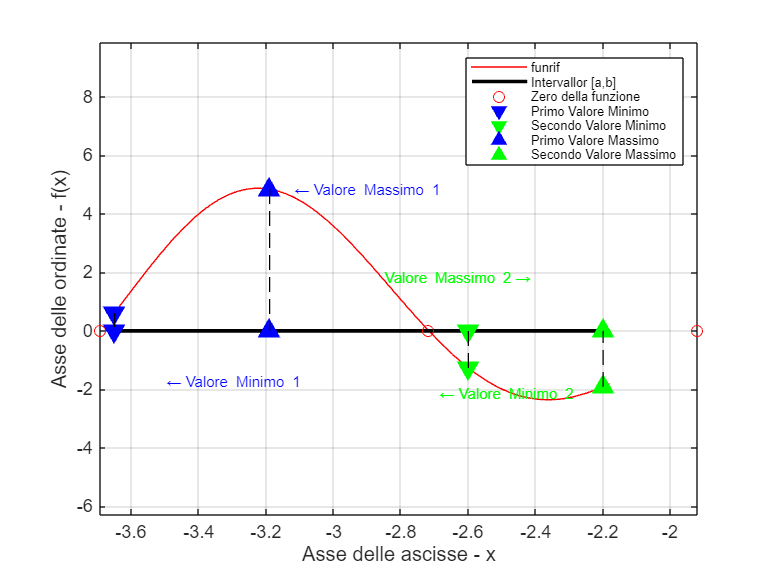

figure(4)
p1 = fplot(funrif, [a, b], 'r', 'DisplayName', 'funrif');
grid on
hold on
p2 = plot([a, b], [0, 0], 'k', 'LineWidth', 2, 'DisplayName', 'Intervallor [a,b]');
xlabel('Asse delle ascisse - x')
ylabel('Asse delle ordinate - f(x)')
p3 = plot(zfzero, 0, 'or', 'DisplayName', 'Zero della funzione');

p4 = plot(minx_1, miny_1, 'v', 'Markersize', 10, 'MarkerFaceColor', 'blue', 'MarkerEdgeColor', 'blue', 'DisplayName', 'Primo Valore Minimo');
plot(minx_1, 0, 'v', 'MarkerEdgeColor', 'b', 'MarkerFaceColor', 'b', 'MarkerSize', 10);
plot([minx_1, minx_1], [miny_1, 0], '--k');

p5 = plot(minx_2, miny_2, 'v', 'MarkerSize', 10, 'MarkerFaceColor', 'green', 'MarkerEdgeColor', 'green' , 'DisplayName', 'Secondo Valore Minimo');
plot(minx_2, 0, 'v', 'MarkerEdgeColor', 'green', 'MarkerFaceColor', 'green', 'MarkerSize', 10);
plot([minx_2, minx_2], [miny_2, 0], '--k');

p6 = plot(maxx_1, maxy_1, '^', 'Markersize', 10, 'MarkerFaceColor', 'blue', 'MarkerEdgeColor', 'blue', 'DisplayName', 'Primo Valore Massimo');
plot(maxx_1, 0, '^', 'MarkerEdgeColor', 'b', 'MarkerFaceColor', 'b', 'MarkerSize', 10);
plot([maxx_1, maxx_1], [maxy_1, 0], '--k');

p7 = plot(maxx_2, maxy_2, '^', 'MarkerSize', 10, 'MarkerFaceColor', 'green', 'MarkerEdgeColor', 'green', 'DisplayName', 'Secondo Valore Massimo');
plot(maxx_2, 0, '^', 'MarkerEdgeColor', 'green', 'MarkerFaceColor', 'green', 'MarkerSize', 10);
plot([maxx_2, maxx_2], [maxy_2, 0], '--k');

text(-3.50, -1.82, '\leftarrowValore Minimo 1', 'Color', 'blue', 'FontSize', 8)
text(-3.12, 4.74, '\leftarrowValore Massimo 1', 'Color', 'blue', 'FontSize', 8)
text(-2.69, -2.24, '\leftarrowValore Minimo 2', 'Color', 'green', 'FontSize', 8)
text(-2.41, 1.72, 'Valore Massimo 2\rightarrow', 'Color', 'green', 'FontSize', 8, 'HorizontalAlignment','right')
legend([p1, p2, p3(i), p4, p5, p6, p7], 'Location', 'northeast', 'FontSize', 7)
ymin = min(miny_1, miny_2) - 5;
ymax = max(maxy_1, maxy_2) + 5;
ylim([ymin ymax]); %%per la scalatura verticale
hold off

## TASK 5

Si calcola la derivata prima di `funrif` con una serie di comandi:

- `syms x `viene utilizzata per realizzare una variabile simbolica;

- `diff(funzione, variabile_simbolica) `calcola la derivata;

- `matlabfunction(funzione_simbolica) `serve per convertire la funzione in simbolica in una function gestita da Matlab.

Il calcolo della derivata prima viene utilizzato nel **metodo di Newton**, richiamato con la funzione `Newton`, che prende come parametri i seguenti dati:

- `funrif: `la funzione corrente($f\left(x\right)$);

- `fprimo`: la derivata prima ($f^{\prime } \left(x\right)$);

- l'`approssimazione iniziale da considerare`;

- `1e-6` : ossia il `delta_ass` definito con l'errore assoluto massimo richiesto sul risultato ed è un reale non negativo. 

Questo metodo, ad ogni iterazione:

- approssima localmente (ossia in un intorno definito di $x_k$) la funzione $f\left(x\right)$ con una retta $t\left(x\right)$;               ($x_{k+1} =x_k -\frac{f\left(x_k \right)}{f^{\prime } \left(x_k \right)}$)

- risolve il problema: $t\left(x\right)=0$ (un problema che risulta essere meno ostico rispetto a quello proposto inizialmente);

- la soluzione della equazione precedentemente descritta nel punto 2, viene considerata come approssimazione (a quel passo) della soluzione di $f\left(x\right)=0$.

Per l'applicabilità del metodo di Newton, dobbiamo considerare:$f\left(x\right),f^{\prime } \left(x\right)\;$e $x_0$ noti. Questo metodo non converge sempre (metodo **locale**) e ha una rapidità di convergenza **quadratica **(risulta essere più efficiente del metodo di bisezione). L'errore si dimezza ad ogni passo. La condizione sufficiente di convergenza è la seguente:

- se $f^{\prime } \left(x\right)\not= 0\;$ e ${f^{\prime } }^{\prime } \left(x\right)$ non cambia segno in $\left\lbrack a,b\right\rbrack$;

- se $f\left(a\right)f\left(b\right)<0$;

- e se $\left|\frac{f\left(a\right)}{f^{\prime } \left(a\right)}\right|<b-a\;,\left|\frac{f\left(b\right)}{f^{\prime } \left(b\right)}\right|<b-a$

allora questo metodo converge per ogni $x_0 \in \left\lbrack a,b\right\rbrack$.

Utilizziamo questo metodo per i primi due zeri. 

syms x
f1 = diff(funrif, x);
fprimo = matlabFunction(f1)

fprimo = function_handle with value:
    @(x)cos(x.*2.0).^2.*exp(x.*(-3.0./5.0)).*(-3.0./5.0)-cos(x.*2.0).*sin(x.*2.0).*exp(x.*(-3.0./5.0)).*4.0+(pi.*cos(x.*pi).*7.0)./(x.^2.*3.0+1.0)-x.*sin(x.*pi).*1.0./(x.^2.*3.0+1.0).^2.*4.2e+1


format long
zN1 = Newton(funrif, fprimo, -3.65, 1e-6, 30)  %%approssimazione del primo zero 

  -3.692148473040876   0.001055846174030   0.014822527960542

  -3.693204319214906   0.000001007284304   0.000014113804547

  -3.693205326499210   0.000000000000925   0.000000000012954



zN1 =   -3.693205326498286


format long
zN2 = Newton(funrif, fprimo, -3.40, 1e-6, 30) %%approssimazione del secondo zero 

  -3.814744738007188   0.163331449910287   1.425038799312222

  -3.651413288096901   0.040785205610940   0.604182643358011

  -3.692198493707841   0.001005918152034   0.014120342887038

  -3.693204411859875   0.000000914639498   0.000012815687551

  -3.693205326499372   0.000000000000762   0.000000000010683



zN2 =   -3.693205326498610


Si adopera per il terzo e il quarto zero, come da consegna, il **metodo di bisezione **richiamato con la funzione `bisezione`, che prende come parametri:

- `funrif`: la funzione corrente $f\left(x\right)$;

- l'`estremo sinistro`;

- l'`estremo destro`;

- `1e-6`: ossia il `delta_ass`;

- `30`: relativo al `kmax` ossia al numero massimo di interazioni (espresso da un valore intero).

Gli estremi sono relativi a quelli che racchiudono l'intervallo che contiene lo zero della funzione.

Questo metodo **converge sempre** (metodo **globale**). Ha una convergenza di tipo** lineare**, l'errore ad un certo passo è proporzionale all'errore del passo precedente. Per l'applicabilità, si devono rendere noti la funzione $f\left(x\right)$ e l'intervallo $\left\lbrack a,b\right\rbrack$. Le condizioni alla base di questo metodo sono:

- $f\left(x\right)$ continua nell'intervallo $\left\lbrack a,b\right\rbrack$;

- $f\left(x\right)$ cambia segno in $\left\lbrack a,b\right\rbrack$ ($f\left(a\right)f\left(b\right)<0$).

format long
zB1 = bisezione(funrif, -3.0, -2.8, 1e-6) %%approssimazione del terzo zero 

zB1 =   -2.800000381469726


format long
zB2 = bisezione(funrif, -2.6, -2.4, 1e-6) %%approssimazione del quarto zero 

zB2 =   -2.400000381469726


Come metodo finale, utilizzato per il quinto zero della funzione, si ha quello delle **secanti**, richiamato dalla funzione `Secanti`, che prende come paramentri:

- `funrif`: la funzione di riferimento $\left(f\left(x\right)\right)$;

- l'`estremo destro` e `sinistro` contenente la soluzione;

- `1e-6` : il `delta_ass`;

- `30`: relativo al `kmax` ossia al numero massimo di interazioni (espresso da un valore intero).

Questo metodo ha una rapidità di convergenza **superlineare** (è più efficiente del metodo di bisezione e meno efficiente del metodo di Newton). Supponiamo che la velocità di convergenza sia di ordine $q$ (per dimostrare la natura della sua rapidità di convergenza). Questo ordine è pari alla** sezione aurea** (**golden section**, rappresentata anche dalla lettera greca $\varphi \;$: "phi") con un valore pari a 1.618. Il metodo delle secanti usa i valori di $f\left(x\right)$ e approssima $f^{\prime } \left(x\right)$. 


$$x_{k+1} =x_k +c_k$$
                        
$$c_{k\;} =-\frac{f\left(x_k \right)}{p_k }$$


format long
zS1 = Secanti(funrif, -2.3, -2.0, 1e-6, 30) %%approssimazione del quinto zero

zS1 =   -1.920072771331829


## `TASK 6`

In questa sezione, si calcolano i **residui** e gli **errori assoluti**. Successivamente, questi valori verranno confrontati con il `delta_ass` e commentati.

Il **residuo** è la misura di quanto una soluzione approssimata soddisfa il problema. 


$$\textrm{res}\left(x_k \right)=\left|f\left(x_k \right)-0\right|=\left|f\left(x_k \right)\right|$$


format long 
errzN1 = abs(zN1 -zfzero(1)) %%errore assoluto tra l'approssimazione e la soluzione calcolata con fzero (primo zero)

errzN1 =      1.849187469815661e-12


format long
residuo_zN1 = abs(funrif(zN1)) %%residuo del primo zero

residuo_zN1 =      2.590949677028220e-11


format long
errzN2 = abs(zN2 -zfzero(2)) %%errore assoluto tra l'approssimazione e la soluzione calcolata con fzero (secondo zero)

errzN2 =      1.525002346625115e-12


format long
residuo_zN2 = abs(funrif(zN2)) %%residuo del secondo zero

residuo_zN2 =      2.136735233193576e-11


format long
errzB1 = abs(zB1 - zfzero(3)) %%errore assoluto tra l'approssimazione e la soluzione calcolata con fzero (terzo zero)

errzB1 =    0.082417952070122


format long
residuo_zB1 = abs(funrif(zB1)) %%residuo del terzo zero

residuo_zB1 =    1.059598370305830


format long
errzB2 = abs(zB2 - zfzero(4)) %%errore assoluto tra l'approssimazione e la soluzione calcolata con fzero (quarto zero)

errzB2 =    0.317582047929878


format long
residuo_zB2 = abs(funrif(zB2)) %%residuo del quarto zero

residuo_zB2 =    2.331875644179054


format long
errzS1 = abs(zS1 - zfzero(5)) %%errore assoluto tra l'approssimazione e la soluzione calcolata con fzero (quinto zero)

errzS1 =      9.801351485982934e-08


format long
residuo_zS1 = abs(funrif(zS1)) %%residuo del quinto zero

residuo_zS1 =      6.885116050625584e-07


- `errzN1` ha un ordine minore di `delta_ass`, ossia pari a ${10}^{-10}$;

- `residuo_zN1 e errzN2 `hanno un ordine pari a ${10}^{-8}$, minore dell'ordine di grandezza di `delta_ass`;

- `residuo_zN2 `ha un ordine pari a quello di `delta_ass` ossia ${10}^{-6}$;

- `residuo_zB1` e `residuo_zB2 `ha un ordine pari a ${10}^{-6}$ uguale a quello a relativo al `delta_ass`;

- `errzB1` ha un ordine uguale a ${10}^{-8}$ minore di `delta_ass`;

- `errzB2 `ha un ordine equivalente a ${10}^{-7}$ minore di `delta_ass;`

- `residuo_zS1 `ha un ordine di grandezza pari a ${10}^{-6}$ pari a quello del `delta_ass`;

- `errzS1 `ha un ordine pari a ${10}^{-7}$ minore di quello del `delta_ass.`

### Cosa si intende per problema mal condizionato o ben condizionato?

Un problema **mal condizionato** è **molto sensibile** a errori sulla funzione. Invece se è **ben condizionato** è **poco sensibile** a errori sulla funzione. L'**analisi del condizionamento** si concentra sull'accertare che la soluzione $r$ abbia o meno lo stesso errore del valore $x$ e della funzione $f\left(x\right)$ (pari a ${10}^{-p}$) . Si può stimare quantitativamente il condizionamento di questo problema tramite il calcolo del valore detto **indice di condizionamento**. La formula è la seguente: $k_f ={\left|f^{\prime } \left(r\right)\right|}^{-1}$ 

format long
ind_cond1 = (abs(fprimo(zN1)))^-1 %%indice di condizionamento relativo al primo zero

ind_cond1 =    0.071368860901422


format long
ind_cond2 = (abs(fprimo(zN2)))^-1 %%indice di condizionamento relativo al secondo zero

ind_cond2 =    0.071368860901464


format long
ind_cond3 = (abs(fprimo(zB1)))^-1 %%indice di condizionamento relativo al terzo zero

ind_cond3 =    0.075274820488426


format long
ind_cond4 = (abs(fprimo(zB2)))^-1 %%indice di condizionamento relativo al quarto zero

ind_cond4 =    0.711186690858709


format long
ind_cond5 = (abs(fprimo(zS1)))^-1 %%indice di condizionamento relativo al quinto zero

ind_cond5 =    0.142355655637856


I problemi degli zeri sono tutti ben condizionati perchè il loro indice di condizionamento è minore di 1 e più vicino allo zero. 

## TASK 7

### Problema del punto fisso: 

#### Definizione 

Data una funzione $g\left(x\right)$ trovare, se esiste, un'ascissa $p$ tale che: $p:p=g\left(p\right)$. $p$ è un punto fisso per $g$ e il suo problema è: $x=g\left(x\right)$. Bisogna, quindi, ricercare un punto sul grafico di $g$ che abbia l'ascissa e l'ordinata uguali, ossia l'ascissa del punto di intersezione del grafico $g$ con la bisettrice del primo quadrante ($y=x$). 


$$x_{k+1} =g\left(x_k \right)$$


#### Condizionamento

Il problema è ben condizionato se la pendenza del grafico della funzione $g$ è diversa dalla pendenza della bisettrice vicino al punto fisso. In caso contrario (quando la pendenza è circa uguale), il problema è mal condizionato (anche quando l'angolo della curva è di 45 gradi e la tangente pari, in questo caso, a uno).

#### Convergenza

La convergenza dipende dalla funzione $g$ e dalla scelta di $x_0$. Il metodo del punto fisso converge a $p$ se la funzione $g$ è una **contrazione**:

**contrazione in I**: $\left|g\left(v\right)-g\left(q\right)\right|\le c\left|v-q\right|$        $c<1,\forall v,q\in I$

Quindi, se $g$ è derivabile e ha derivata minore di 1 (in valore assoluto), allora il metodo del punto fisso converge a $p$, scegliendo $x_0$ vicino a $p$. 

La velocità di convergenza è:

- **lineare** (generalmente) con costante di proporzionalità $c$ pari a: $\left|g^{\prime } \left(p\right)\right|$ (al diminuire di $c$ aumenta la velocità di convergenza);

- **quadratica** se $g^{\prime } \left(p\right)=0$ (converge molto rapidamente).

Come da consegna, si calcolano inizialmente con la funzione `fzero` (oppurtunamente adattata al problema in questione) i due punti fissi della funzione in un sottointervallo di $\left\lbrack -4,1\right\rbrack$ ossia $\left\lbrack -1\ldotp 28073,0\ldotp 823484\right\rbrack$. 

L'argomento della funzione `fzero`, ossia `'@(x) funrif(x) - x',` esprime l'adattamento della funzione al problema richiesto dal punto fisso, ossia $x=g\left(x\right)$, 

format long
pfisso1 = fzero(@(x) funrif(x) - x, 0.00442765) %%ascissa del primo punto fisso

pfisso1 =    0.050121273363690


format long
y_fisso1 = funrif(pfisso1) %%ordinata del primo punto fisso

y_fisso1 =    0.050121273363690


format long
pfisso2 = fzero(@(x) funrif(x) - x, -1.178) %%ascissa del secondo punto fisso

pfisso2 =   -1.073695868807284


format long
y_fisso2 = funrif(pfisso2) %%ordinata del secondo punto fisso

y_fisso2 =   -1.073695868807284


Vengono calcolati, poi, i residui di entrambi i punti fissi:

format long
residuo_pf1 = abs(funrif(pfisso1)) %%residuo del primo punto fisso

residuo_pf1 =    0.050121273363690


format long
residuo_pf2 = abs(funrif(pfisso2))  %%residuo del secondo punto fisso

residuo_pf2 =    1.073695868807284


Dopo queste procedure, si controlla se il metodo `fzero` convergerebbe a tali punti, semplicemente controllando che il valore assoluto della derivata prima in questi punti sia minore di 1 (come detto precedentemente nella descrizione e definizione generale del problema del punto fisso):

format long
dv_p1 = abs(fprimo(pfisso1)) %%derivata calcolata nel primo punto fisso

dv_p1 =   20.268563330447900


format long
dv_p2 = abs(fprimo(pfisso2)) %%derivata calcolata nel secondo punto fisso

dv_p2 =    8.101567745589982


Il metodo non converge in questi punti fissi perchè i valori delle derivate in essi non sono minori di 1.

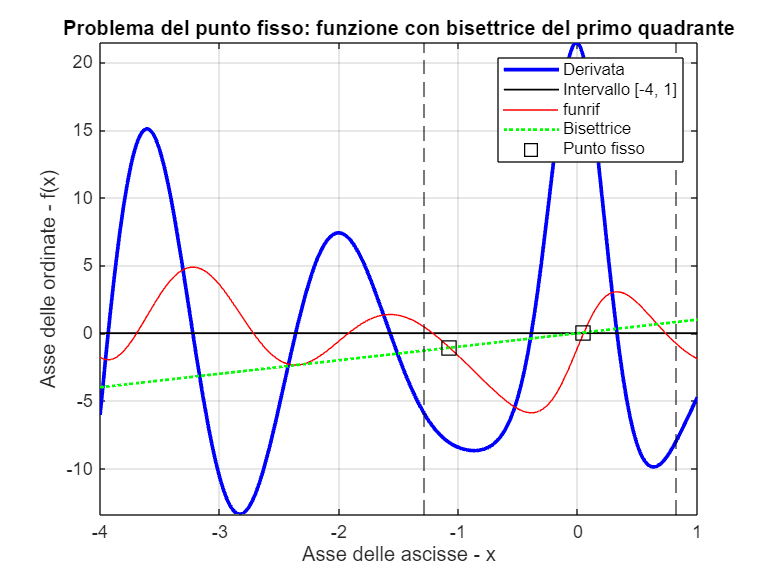

figure(5)
pl = fplot(fprimo, [-4, 1], 'blue','LineWidth', 2, 'DisplayName', 'Derivata');
grid on
hold on
pl_0 = plot([-4, 1], [0, 0], '-k', 'LineWidth', 1, 'DisplayName', 'Intervallo [-4, 1]');
pl_1 = fplot(funrif, [-4, 1], 'r', 'DisplayName', 'funrif');
pl_2 = plot([-4, 1], [-4, 1], ':green', 'LineWidth', 1.5, 'DisplayName', 'Bisettrice');
xl_1 = xline(-1.28073, '--k'); %%utilizzata per visualizzare la linea tratteggiata che delimita l'intervallo nel quale si trovano i punti fissi
xl_2 = xline(0.823484, '--k');
pl_3 = plot(pfisso1, y_fisso1, 'ks', 'MarkerSize', 10, 'DisplayName', 'Punto fisso', 'LineWidth', 1);
pl_4 = plot(pfisso2, y_fisso2, 'ks', 'MarkerSize', 10, 'DisplayName', 'Punto fisso', 'LineWidth', 1);
plot_pfissi = [pl_3 pl_4];
title('Problema del punto fisso: funzione con bisettrice del primo quadrante')
legend([pl, pl_0, pl_1, pl_2, plot_pfissi(1)], 'Location', 'northeast')
xlabel('Asse delle ascisse - x')
ylabel('Asse delle ordinate - f(x)')
hold off

Il problema è ben condizionato perchè la pendenza della bisettrice e della funzione `funrif `sono diverse nei punti fissi. 

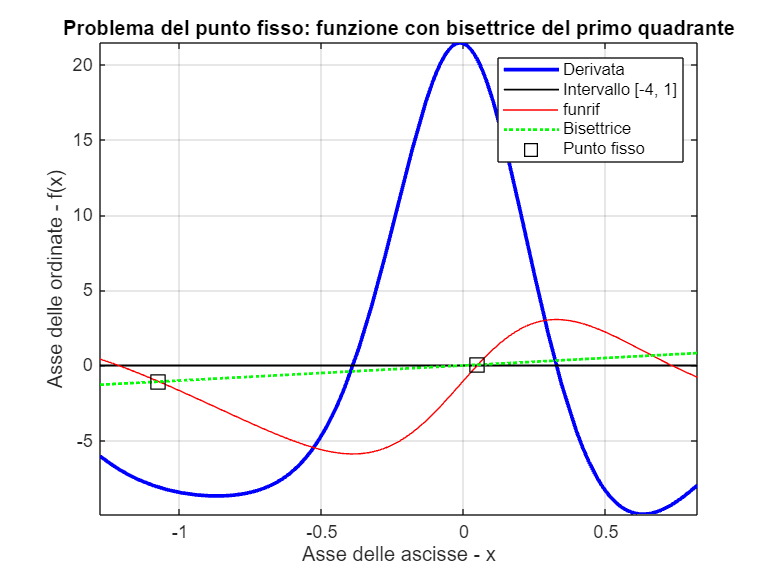

figure(6)
x = linspace(-1.28073, 0, 0.823484);
plt  = fplot(fprimo, [-1.28073, 0.823484], 'blue','LineWidth', 2, 'DisplayName', 'Derivata');
grid on
hold on
plt_0 = plot([-1.28073, 0.823484], [0, 0], '-k', 'LineWidth', 1, 'DisplayName', 'Intervallo [-4, 1]');
plt_1 = fplot(funrif, [-1.28073, 0.823484], 'r', 'DisplayName', 'funrif');
plt_2 = plot([-1.28073, 0, 0.823484], [-1.28073, 0, 0.823484], ':green', 'LineWidth', 1.5, 'DisplayName', 'Bisettrice');
plt_3 = plot(pfisso1, y_fisso1, 'ks', 'MarkerSize', 10, 'DisplayName', 'Punto fisso', 'LineWidth', 1);
plt_4 = plot(pfisso2, y_fisso2, 'ks', 'MarkerSize', 10, 'DisplayName', 'Punto fisso', 'LineWidth', 1);
title('Problema del punto fisso: funzione con bisettrice del primo quadrante')
legend([plt, plt_0, plt_1, plt_2, plot_pfissi(1)], 'Location', 'northeast')
xlabel('Asse delle ascisse - x')
ylabel('Asse delle ordinate - f(x)')
hold off

## TASK 8

Si calcolano i minimi e i massimi con la funzione `fminbnd` con i seguenti parametri:

- la funzione di riferimento `funrif;`

- `estremo sinistro`;

- `estremo destro`;

- l'opzione `optimset('TolX', 1e-10) `imposta il parametro `'TolX' `che riguarda la tolleranza sull'incremento della variabile di ottimizzazione a `'1e-10'`. 

format long
xmin_1 = fminbnd(funrif, -3.65, -3.40, optimset('TolX', 1e-10)) %%primo punto di minimo calcolato con l'opzione optimset

xmin_1 =   -3.649999920049945


format long
ymin_1 = funrif(xmin_1) %%ordinata del primo minimo

ymin_1 =    0.625132660633527


format long
xmin_2 = fminbnd(funrif, -2.80, -2.60, optimset('TolX', 1e-10))  %%secondo punto di minimo calcolato con l'opzione optimset

xmin_2 =   -2.600000066437480


format long
ymin_2 = funrif(xmin_2) %%ordinata del secondo minimo

ymin_2 =   -1.268248215350583


format long
xmax_1 = fminbnd(@(x) -funrif(x), -3.24909, -3.07962, optimset('TolX', 1e-10))  %%primo punto di massimo calcolato con l'opzione optimset

xmax_1 =   -3.223943057556828


format long
ymax_1 = funrif(xmax_1) %%ordinata del primo massimo

ymax_1 =    4.874356424495103


format long
xmax_2 = fminbnd(@(x) -funrif(x), -2.44727, -2.30103, optimset('TolX', 1e-10))  %%secondo punto di massimo calcolato con l'opzione optimset

xmax_2 =   -2.447269957897886


format long
ymax_2  = funrif(xmax_2) %%ordinata del secondo massimo

ymax_2 =   -2.221521587160924


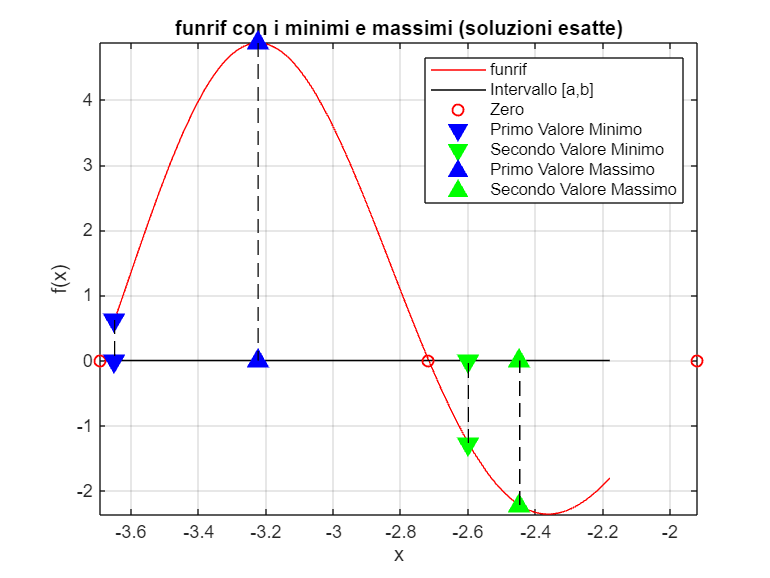

figure(7)
p8 = fplot(funrif, [a, b], 'r', 'DisplayName', 'funrif');
grid on
hold on
p9 = plot([a, b], [0, 0], 'k', 'DisplayName', 'Intervallo [a,b]');
p10 = plot(zfzero, 0, 'o', 'MarkerEdgeColor' , 'red', 'DisplayName', 'Zero', 'LineWidth', 1);

p11 = plot(xmin_1, ymin_1, 'v', 'Markersize', 10, 'MarkerFaceColor', 'blue', 'MarkerEdgeColor', 'blue', 'DisplayName', 'Primo Valore Minimo');
plot(xmin_1, 0, 'v', 'MarkerEdgeColor', 'blue', 'MarkerFaceColor', 'blue', 'MarkerSize', 10);
plot([xmin_1, xmin_1], [ymin_1, 0], '--k');

p12 = plot(xmin_2, ymin_2, 'v', 'MarkerSize', 10, 'MarkerFaceColor', 'green', 'MarkerEdgeColor', 'green' , 'DisplayName', 'Secondo Valore Minimo');
plot(xmin_2, 0, 'v', 'MarkerEdgeColor', 'green', 'MarkerFaceColor', 'green', 'MarkerSize', 10);
plot([xmin_2, xmin_2], [ymin_2, 0], '--k');

p13 = plot(xmax_1, ymax_1, '^', 'Markersize', 10, 'MarkerFaceColor', 'blue', 'MarkerEdgeColor', 'blue', 'DisplayName', 'Primo Valore Massimo');
plot(xmax_1, 0, '^', 'MarkerEdgeColor', 'blue', 'MarkerFaceColor', 'blue', 'MarkerSize', 10);
plot([xmax_1, xmax_1], [ymax_1, 0], '--k');

p14 = plot(xmax_2, ymax_2, '^', 'MarkerSize', 10, 'MarkerFaceColor', 'green', 'MarkerEdgeColor', 'green', 'DisplayName', 'Secondo Valore Massimo');
plot(xmax_2, 0, '^', 'MarkerEdgeColor', 'green', 'MarkerFaceColor', 'green', 'MarkerSize', 10);
plot([xmax_2, xmax_2], [ymax_2, 0], '--k');

legend([p8, p9, p10(i), p11, p12, p13, p14], 'Location','northeast')
title('funrif con i minimi e massimi (soluzioni esatte)')
xlabel('x')
ylabel('f(x)')
hold off

Riconosciamo queste soluzioni come esatte per i calcoli successivi.

## TASK 9

Come da consegna, sono stati trovati gli zeri della derivata prima (rappresentati con dei punti neri nella` figure(8)` ) per confrontarli con i valori dei due massimi e dei due minimi della funzione. 

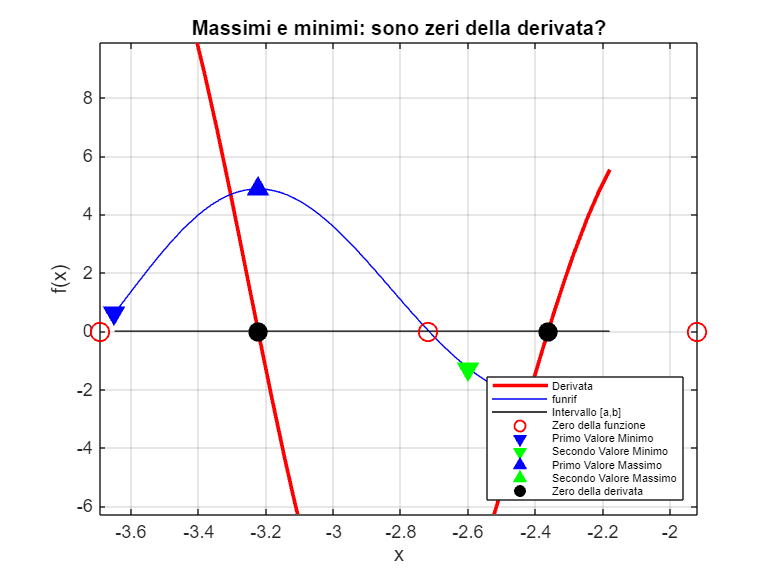

dv_appriniz = [-3.53 -3.16 -2.74 -2.37];
dv_zfzero = zeros(1,4);
for i = 1:4
   dv_zfzero(i) = fzero(fprimo, dv_appriniz(i)); %%dv_zfzero è il vettore che contiene gli zeri della derivata
end
figure(8)
p15 = fplot(fprimo, [a, b], 'r','LineWidth', 2, 'DisplayName', 'Derivata');
grid on
hold on
p16 = fplot(funrif, [a, b], 'blue', 'DisplayName', 'funrif');
p17 = plot([a, b], [0, 0], 'k', 'DisplayName', 'Intervallo [a,b]');
p18 = plot(zfzero, 0, 'o', 'MarkerEdgeColor' , 'red', 'DisplayName', 'Zero della funzione', 'MarkerSize', 10, 'LineWidth', 1);
p19 = plot(xmin_1 , ymin_1, 'v', 'Markersize', 10, 'MarkerFaceColor', 'blue', 'MarkerEdgeColor', 'blue', 'DisplayName', 'Primo Valore Minimo');
p20 = plot(xmin_2 , ymin_2,  'v', 'MarkerSize', 10, 'MarkerFaceColor', 'green', 'MarkerEdgeColor', 'green' , 'DisplayName', 'Secondo Valore Minimo');
p21 = plot(xmax_1 , ymax_1,  '^', 'Markersize', 10, 'MarkerFaceColor', 'blue', 'MarkerEdgeColor', 'blue', 'DisplayName', 'Primo Valore Massimo');
p22 = plot(xmax_2 , ymax_2,  '^', 'MarkerSize', 10, 'MarkerFaceColor', 'green', 'MarkerEdgeColor', 'green', 'DisplayName', 'Secondo Valore Massimo');
p23 = plot(dv_zfzero, 0, 'o', 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'k', 'DisplayName', 'Zero della derivata', 'MarkerSize', 10);
legend([p15, p16, p17, p18(i), p19, p20, p21, p22, p23(i)], 'Location','southeast', 'FontSize', 6)
title('Massimi e minimi: sono zeri della derivata?')
xlabel('x')
ylabel('f(x)')
ymin = min(ymin_1, ymin_2) - 5;
ymax = max(ymax_1, ymax_2) + 5;
ylim([ymin, ymax]);
hold off

dv_zfzero(1) %%primo zero della derivata

ans =   -3.223943053360422


xmin_1 %%soluzione esatta del primo punto di minimo

xmin_1 =   -3.649999920049945


Il primo zero della derivata (`dv_zfzero(1)`) e il primo punto di minimo(`xmin_1`) hanno valori simili. Possiamo affermare, quindi, che il primo minimo è anche zero della derivata. 

dv_zfzero(2) %%secondo zero della derivata

ans =   -3.223943053360422


xmax_1 %%soluzione esatta del primo punto di massimo

xmax_1 =   -3.223943057556828


dv_zfzero(3) %%terzo zero della derivata

ans =   -2.363146762754122


xmin_2 %%soluzione esatta del secondo punto di minimo

xmin_2 =   -2.600000066437480


dv_zfzero(4) %%quarto zero della derivata

ans =   -2.363146762754122


xmax_2 %%soluzione esatta del secondo punto di massimo

xmax_2 =   -2.447269957897886


Si può osservare che anche il punto del secondo minimo (`xmin_2`)  e i punti dei due massimi (`xmax_1`, `xmax_2`) hanno valori simili a quelli relativi, rispettivamente, a: `dv_zfzero(3)`, `dv_zfzero(2) `e `dv_zfzero(4)` . 

Infine, con i calcoli effettuati precedentemente, è evidente che i due minimi e i due massimi sono zeri della derivata prima di `funrif`. 

## TASK 10

In questa sezione, sono calcolate le approssimazioni dei due punti di minimo con il metodo di **Fibonacci Search** (richiamato dalla funzione `fminfibo(funzione_riferimento, estremo_sinistro, estremo_destro, delta_ass)`) e dei due punti di massimo utilizzando il metodo di **Golden Search **(adoperato grazie alla funzione `fmingolden(funzione_riferimento, estremo_sinistro, estremo_destro, delta_ass)`). 

### Metodo di Fibonacci Search

Questo metodo, come quello di Golden Search, "racchiude" la soluzione. Con una valutazione di funzione, c'è la riduzione di un intervallo che racchiude uno zero di una funzione continua. Con due valutazioni di funzione, si riduce l'intervallo che racchiude un minimo di una **funzione unimodale** (ossia una funzione con un unico punto di minimo). I passi del metodo sono i seguenti:

- Si sceglie un numero intero N e si considerano i numeri di Fibonacci: `fibonacci(N)`, `fibonacci(N-1)`, `fibonacci(N-2)`;


$$c=\frac{a+\textrm{fibonacci}\left(N-2\right)\;}{\textrm{fibonacci}\left(N\right)*\left(b-a\right)}$$
        
$$d=\frac{a+\textrm{fibonacci}\left(N-1\right)}{\textrm{fibonacci}\left(N\right)*\left(b-a\right)}$$
  

se $f\left(c\right)<f\left(d\right)\;$il nuovo intervallo è $\left\lbrack a,d\right\rbrack$; se $f\left(c\right)\ge f\left(d\right)$ il nuovo intervallo è $\left\lbrack c,b\right\rbrack$. 

(l'intervallo che contiene la soluzione è $\left\lbrack a,b\right\rbrack$);

         2. $c=\frac{a+\textrm{fibonacci}\left(N-3\right)\;}{\textrm{fibonacci}\left(N-1\right)*\left(b-a\right)}$        $d=\frac{a+\textrm{fibonacci}\left(N-2\right)\;}{\textrm{fibonacci}\left(N-1\right)*\left(b-a\right)}$        

( l'intervallo è chiamato ancora $\left\lbrack a,b\right\rbrack$ ). Si sceglie il nuovo intervallo e così via, fino al passo N-simo).

I due nuovi intervalli $\left\lbrack a,d\right\rbrack$ e $\left\lbrack c,b\right\rbrack$ hanno uguale ampiezza (rappresentate da $d-a$ e $b-c$). 


$$d=\frac{a+\textrm{fibonacci}\left(N-1\right)\;}{\textrm{fibonacci}\left(N\right)*\left(b-a\right)}$$
                   
$$d-a=\left(b-a\right)\frac{F_{N-1} }{F_N }$$


$F_{N-1}$ e $F_N$ sono numeri di Fibonacci. 

 
$$b-c=\left(b-a\right)-\left(b-a\right)\frac{F_{N-2} }{F_N }=\left(b-a\right)\left(1-\frac{F_{N-2} }{F_N }\right)$$


$\left\lbrack a,d\right\rbrack$ e $\left\lbrack c,b\right\rbrack$ hanno uguale ampiezza:


$$\left(b-a\right)\left(\frac{{F_N -F}_{N-2} }{F_N }\right)=\left(b-a\right)\frac{F_{N-1} }{F_N }$$
        
$$F_N =F_{N-1} +F_{N-2}$$


L'intervallo finale è $\left\lbrack b,a\right\rbrack \frac{1}{F_N }$ .

Dopo $N$ passi l'ampiezza dell'intervallo iniziale $\left\lbrack a,b\right\rbrack$ si riduce a $\frac{1}{F_N }$ dove $F_N \approx \varphi^N$ .

$\varphi$ è chiamata **sezione aurea** (**golden section**) e si legge "phi". 

## Metodo di Golden Search

$\lim_{n\to \infty } \frac{F_n }{F_{n-1} }=\varphi$ dove $\varphi$ è uguale a 1.6180. 

$\lim_{n\to \infty } \;\;\;\frac{F_{n-1} }{F_n }=\frac{1}{\varphi }\;=\varphi -1\;$    0.6180

Nel primo passo avremo che:

- $c=a+\left(\left.2-\varphi \right)*\left(b-a\right)\right)$     $\left\lbrack a,b\right\rbrack$ e $\left\lbrack c,b\right\rbrack$ hanno la stessa ampiezza.

- $d=a\;+\left(\varphi -1\right)*\left(b-a\right)$ ;

- L'intervallo che contiene la soluzione è $\left\lbrack a,b\right\rbrack$.

Dopo ogni passo, l'ampiezza dell'intervallo si riduce di un fattore $\frac{1}{\varphi }$. Dopo $N$ passi l'ampiezza dell'intervallo iniziale $\left\lbrack a,b\right\rbrack$ si riduce di un fattore $\frac{1}{\varphi^N }$ .

format long
m1Fibo = fminfibo(funrif, -3.65152, -3.40895, 1e-3) %%approssimazione del primo punto di minimo

m1Fibo =   -3.649835486111111


format long
m2Fibo = fminfibo(funrif, -2.8000, -2.6000, 1e-3) %%approssimazione del secondo punto di minimo

m2Fibo =   -2.601388888888889


format long
MGolden1 = fmingolden(@(x) - funrif(x), -3.20396, -3.12654, 1e-3) %%approssimazione del primo punto di massimo

MGolden1 =   -3.203645263747964


format long
MGolden2 = fmingolden(@(x) - funrif(x), -2.41942, -2.33349, 1e-3) %%approssimazione del secondo punto di massimo

MGolden2 =   -2.419070667965158


## TASK 11

In questa sezione, verranno commentati e verificati i valori degli **errori assoluti**. 

format long
errmF1 = abs(m1Fibo - xmin_1) %%errore assoluto tra l'approssimazione del primo punto di minimo e la sua soluzione esatta

errmF1 =      1.644339388335858e-04


format long
errmF2 = abs(m2Fibo - xmin_2) %%errore assoluto tra l'approssimazione del secondo punto di minimo e la sua soluzione esatta

errmF2 =    0.001388822451409


format long
errMG1 = abs(MGolden1 - xmax_1) %%errore assoluto tra l'approssimazione del primo punto di massimo e la sua soluzione esatta

errMG1 =    0.020297793808864


format long
errMG2= abs(MGolden2 - xmax_2) %%errore assoluto tra l'approssimazione del secondo punto di massimo e la sua soluzione esatta

errMG2 =    0.028199289932728


- `errmF1 `ed `errmF2 `: hanno un ordine di grandezza, ossia ${10}^{-4}$ ,  minore di quello di `delta_ass` (pari a ${10}^{-3}$);

- mentre `errMG1` ed `errMG2 `: hanno un ordine di grandezza maggiore dell'accuratezza richiesta, ossia ${10}^{-3}$(relativo a `delta_ass`).

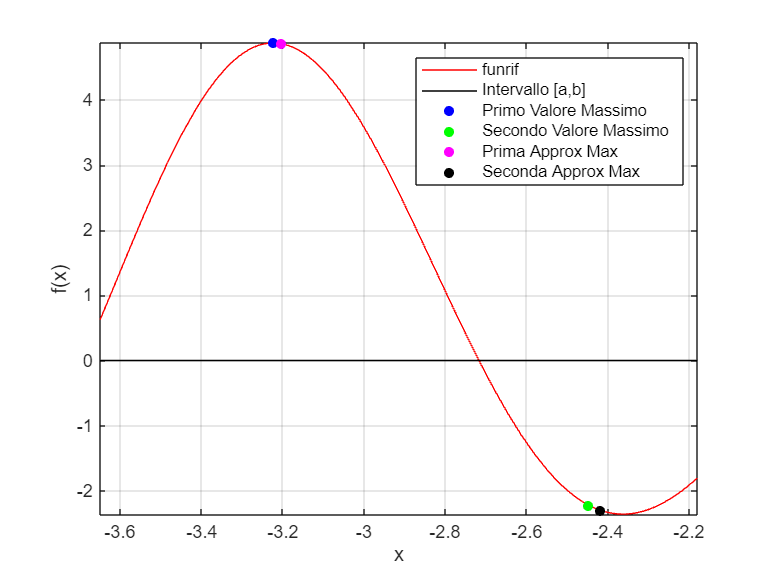

figure(9)
plt_5 = fplot(funrif, [a, b], 'r', 'DisplayName', 'funrif');
grid on
hold on
plt_6 = plot([a, b], [0, 0], 'k', 'DisplayName', 'Intervallo [a,b]');
plt_7 = plot(xmax_1, ymax_1, 'o', 'Markersize', 5, 'MarkerFaceColor', 'blue', 'MarkerEdgeColor', 'blue', 'DisplayName', 'Primo Valore Massimo');
plt_8 = plot(xmax_2, ymax_2, 'o', 'MarkerSize', 5, 'MarkerFaceColor', 'green', 'MarkerEdgeColor', 'green' , 'DisplayName', 'Secondo Valore Massimo');
plt_9 = plot(MGolden1, funrif(MGolden1), 'o', 'Markersize', 5, 'MarkerFaceColor', 'magenta', 'MarkerEdgeColor', 'magenta', 'DisplayName', 'Prima Approx Max');
plt_10 = plot(MGolden2, funrif(MGolden2), 'o', 'MarkerSize', 5, 'MarkerFaceColor', 'k', 'MarkerEdgeColor', 'k', 'DisplayName', 'Seconda Approx Max');
legend([plt_5, plt_6, plt_7, plt_8, plt_9, plt_10], 'Location','northeast')
xlabel('x')
ylabel('f(x)')
hold off

Si può notare, anche dal grafico (`figure(9)`), che i valori distano di una determinata quantità pari all'errore tra le approssimazioni e le soluzioni esatte.

Proviamo, quindi, a calcolare le approssimazioni dei punti di massimo con il metodo di Fibonacci. La funzione, a questo punto, deve essere inserita con il segno opposto come parametro (perchè questo metodo è indicato per il calcolo delle approssimazioni dei minimi).

format long
maxF1 = fminfibo(@(x) - funrif(x), -3.20396, -3.12654, 1e-3) %%approssimazione del primo massimo con il metodo di Fibonacci

maxF1 =   -3.202552363636364


format long
maxF2 = fminfibo( @(x) - funrif(x), -2.41942, -2.33349, 1e-3) %%approssimazione del secondo massimo con il metodo di Fibonacci

maxF2 =   -2.417857636363637


format long 
errFM1 = abs(maxF1 - xmax_1) %%errore assoluto tra l'approssimazione calcolata con il metodo di Fibonacci e la soluzione esatta (primo massimo)

errFM1 =    0.021390693920464


format long
errFM2 = abs(maxF2 - xmax_2)%%errore assoluto tra l'approssimazione calcolata con il metodo di Fibonacci e la soluzione esatta (secondo massimo)

errFM2 =    0.029412321534250


In questo caso, l'errore assoluto sia per il primo punto di massimo (`errFM1`) che per il secondo punto di massimo (`errFM2`), calcolati con il metodo di Fibonacci, risultano essere di ordine inferiore(${10}^{-4}$) rispetto all'accuratezza richiesta ossia ${10}^{-3}$ (`delta_ass`).